# Assignment 3

#### Let us consider two one-dimensional normal distributions with mean m1 = 1 and m2 = −3, with standard deviations s1 = s2 = √2. The two distributions have same prior probability P(w1 ) = P(w2) = 0.5. Compute the value of the decision criterion x*. Briefly comment on the approach that you take and report the main steps of the calculations.

% Given data
m1 = 1;
m2 = -3;
s1 = sqrt(2);
s2 = sqrt(2);
p_w1 = 0.5;
p_w2 = 0.5;

% Solve the equation P(ω1)p(x|ω1) = P(ω2)p(x|ω2)
sympref('FloatingPointOutput', true);
syms x
eqn = p_w1*(1/(s1*sqrt(2*pi)))*exp(-(x-m1)^2/(2*s1^2)) == p_w2*(1/(s2*sqrt(2*pi)))*exp(-(x-m2)^2/(2*s2^2));
xSol = solve(eqn, x);
fprintf("The value of the decision criterion x* is %i.", xSol);

The value of the decision criterion x* is -1.

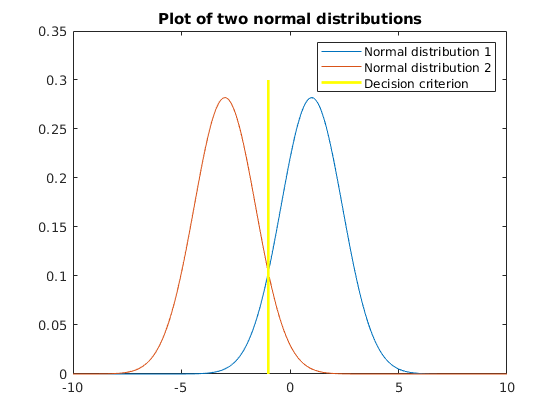


% Let's make a visual example
% Compute normal distributions
xrange = -10:0.1:10;
norm1 = normpdf(xrange, m1, s1);
norm2 = normpdf(xrange, m2, s2);
% Compute joint probability of d1 and d2
p1 = norm1 * p_w1;
p2 = norm2 * p_w2;
% Plot the decision criterion in the graph as a line
plot_norm1 = plot(xrange, norm1);
hold on
plot_norm2 = plot(xrange, norm2);
pdc = line([xSol, xSol], ylim, 'LineWidth', 2, 'Color', 'y');
title('Plot of two normal distributions');
legend([plot_norm1, plot_norm2, pdc], 'Normal distribution 1', 'Normal distribution 2', 'Decision criterion');
hold off